# **W3 Probabilistic Road Map**

#### **Robotics: Computational Motion Planning**

**University of Pennsylvania  |  Coursera**

clear;
close all;
clc;

## Drawing the robot

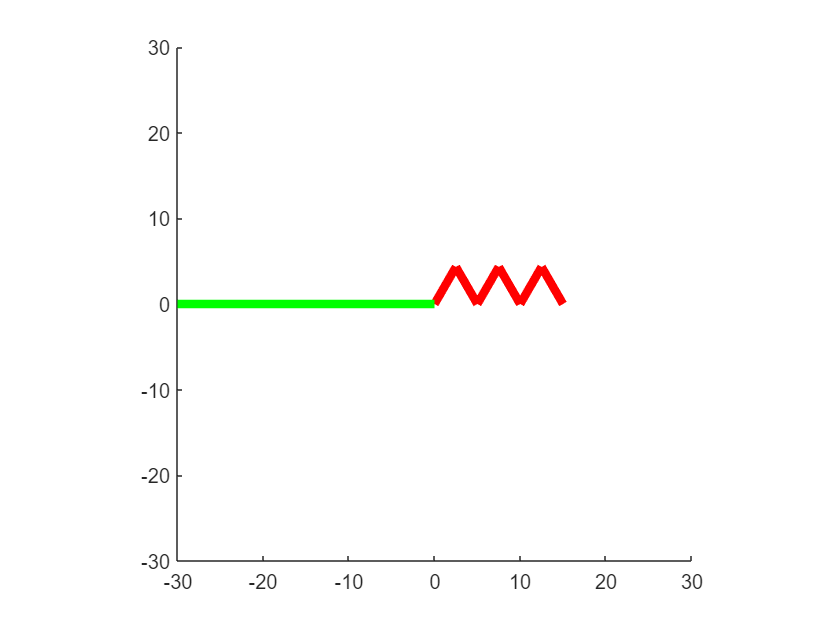

figure;

% The SixLinkRobot function computes layout of all of the links in the
% robot as a function of the 6 configuration space parameters. You can
% adjust these sixe numbers to see what happens.
fv = SixLinkRobot ([-120 120 -120 120 -120 60]);
fv2 = SixLinkRobot ([0 0 0 0 0 180]);

p = patch (fv);

p.FaceColor = 'red';
p.EdgeColor = 'none';

p2 = patch(fv2);
p2.FaceColor = 'green';
p2.EdgeColor = 'none';

sz = 30;
axis equal;
axis (sz*[-1 1 -1 1]);

## Add Obstacles

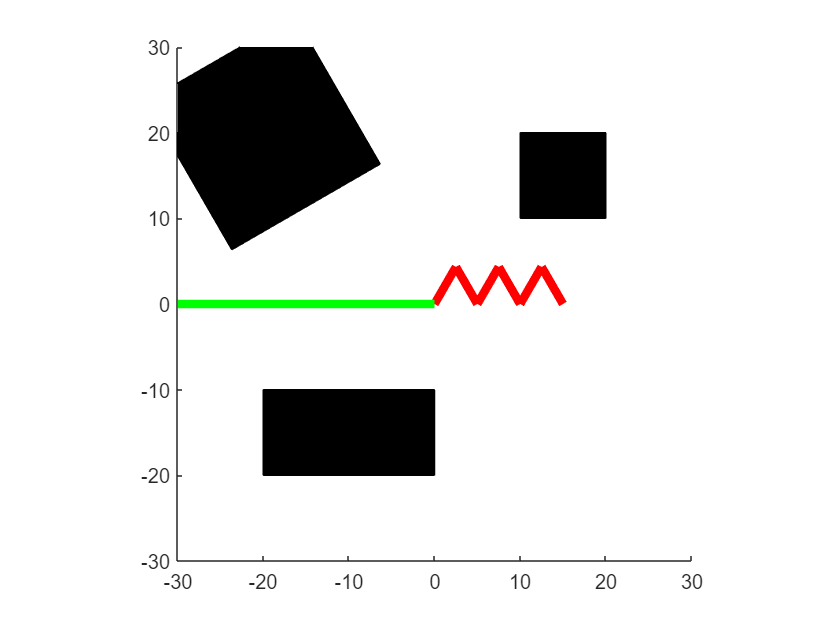

obstacle = boxFV(10, 20, 10, 20);
obstacle = appendFV (obstacle, boxFV(-20, 0, -20, -10));
obstacle = appendFV (obstacle, transformFV(boxFV(-10, 10, -10, 10), 30, [-20 20]));

patch (obstacle);

## Build Roadmap

nsamples = 200;
neighbors = 5;

roadmap = PRM (@()(RandomSampleSixLink(obstacle)), @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), nsamples, neighbors);

nsamples = 2, nedges = 0
nsamples = 3, nedges = 2
nsamples = 4, nedges = 2
nsamples = 5, nedges = 5
nsamples = 6, nedges = 8
nsamples = 7, nedges = 10
nsamples = 8, nedges = 13
nsamples = 9, nedges = 16
nsamples = 10, nedges = 21
nsamples = 11, nedges = 26
nsamples = 12, nedges = 31
nsamples = 13, nedges = 34
nsamples = 14, nedges = 37
nsamples = 15, nedges = 39
nsamples = 16, nedges = 43
nsamples = 17, nedges = 46
nsamples = 18, nedges = 50
nsamples = 19, nedges = 54
nsamples = 20, nedges = 56
nsamples = 21, nedges = 59
nsamples = 22, nedges = 63
nsamples = 23, nedges = 66
nsamples = 24, nedges = 69
nsamples = 25, nedges = 73
nsamples = 26, nedges = 78
nsamples = 27, nedges = 82
nsamples = 28, nedges = 86
nsamples = 29, nedges = 91
nsamples = 30, nedges = 96
nsamples = 31, nedges = 100
nsamples = 32, nedges = 105
nsamples = 33, nedges = 108
nsamples = 34, nedges = 112
nsamples = 35, nedges = 117
nsamples = 36, nedges = 120
nsamples = 37, nedges = 124
nsamples = 38, nedges = 128
nsampl

## Add Nodes

roadmap2 = AddNode2PRM ([240 120 240 120 240 60]', roadmap, @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), neighbors);
roadmap2 = AddNode2PRM ([0 0 0 0 0 180]', roadmap2, @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), neighbors);

## Plan a Route

route = ShortestPathDijkstra(roadmap2.edges, roadmap2.edge_lengths, nsamples+1, nsamples+2);

## Plot the Trajectory

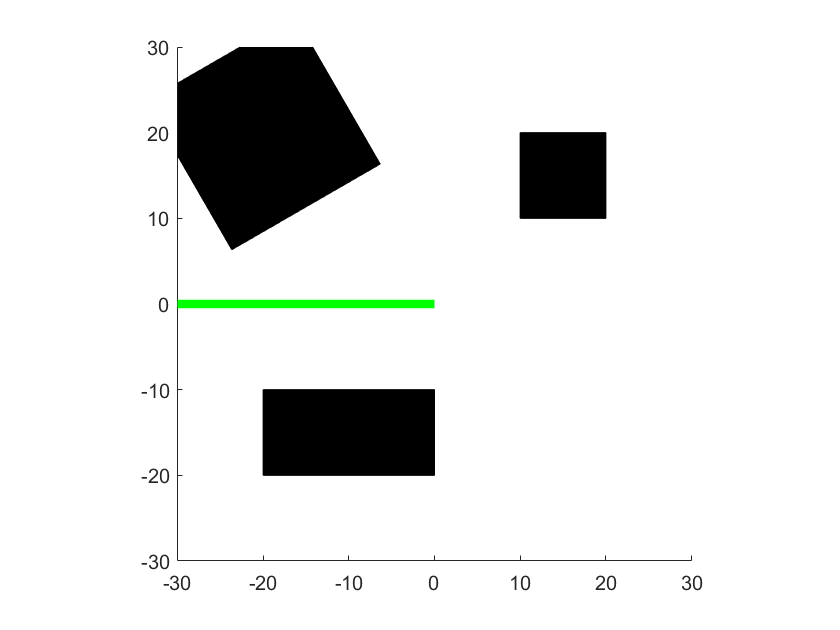

for i = 2:length(route)
    x1 = roadmap2.samples(:,route(i-1));
    x2 = roadmap2.samples(:,route(i));
    
    delta = x2 - x1;
    
    t = delta > 180;
    delta(t) = delta(t) - 360;
    
    t = delta < -180;
    delta(t) = delta(t) + 360;
    
    n = ceil(sum(abs(delta)) / 10);
    
    for j = 0:n
        x = mod(x1 + (j/n)*delta, 360);
        fv = SixLinkRobot (x);
        p.Vertices = fv.vertices;
        
        drawnow;
        pause(0.01);
        
        if (CollisionCheck(fv, obstacle))
            fprintf (1, 'Ouch\n');
        end
    end
end